## Clément interpolation discussion

### Preliminars

Mesh on which the *given* (or input) function will be projected and filtered. Consider the following discretization of a [0,1]x[0,1] domain:

clear;
x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh(m);

Moreover, we need a *given L2 *function:

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

iPar.mesh     = mesh;
iPar.quadType = 'QUADRATICMASS';
error         = IntegratorError(iPar);

### Projections

Let's project previous L2 function into a P0 FE function:

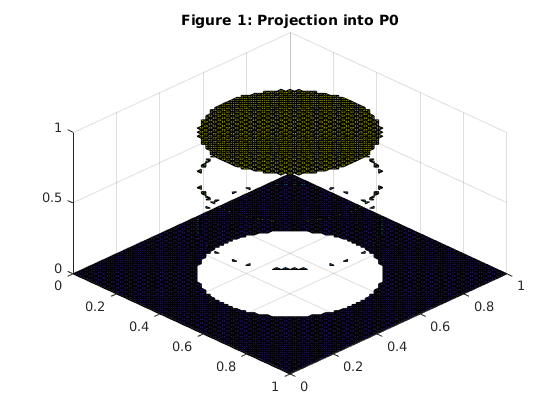

fP0 = fun.project('P0');
fP0.plot()
view(45,45)
title('Figure 1: Projection into P0')

error.compute(fP0,fun)

ans = 0.0014

Let's now project it into a P1 FE function:

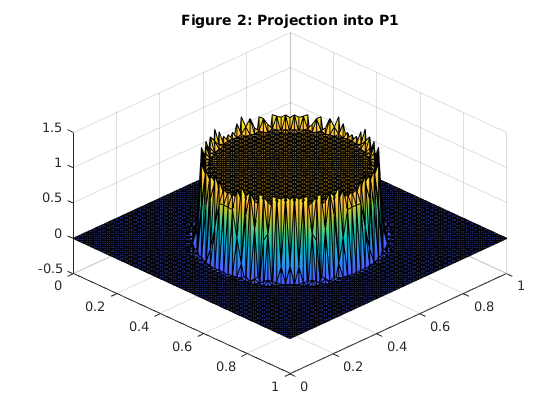

fP1 = fun.project('P1');
fP1.plot()
view(45,45)
title('Figure 2: Projection into P1')

error.compute(fP1,fun)

ans = 0.0013

Let's now project it into a P1 FE function using a lumped mass matrix:

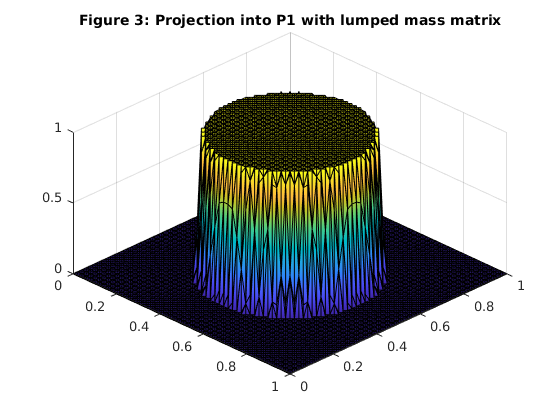

newProj = Projector_toP1Lumped(s);
fP1Lump = newProj.project(fun);
fP1Lump.plot()
view(45,45)
title('Figure 3: Projection into P1 with lumped mass matrix')

error.compute(fP1Lump,fun)

ans = 0.0018

### PDE Filter

Let's create now a PDE filter, which smooths isotropically just the internal boundaries:

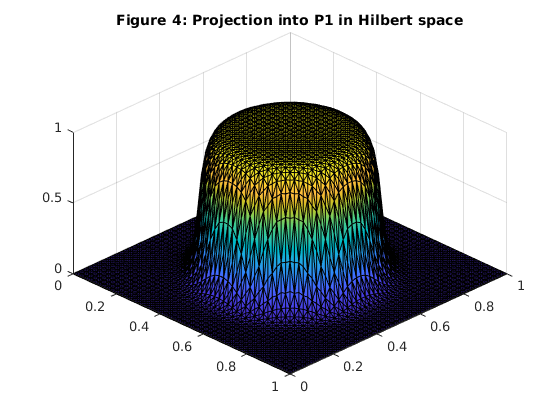

ss.filterType   = 'PDE';
ss.mesh         = mesh;
ss.boundaryType = 'Neumann';
ss.metric       = 'Isotropy';
filter          = Filter.create(ss);
fP1PDE          = filter.compute(fun,'QUADRATICMASS');
fP1PDE.plot()
view(45,45)
title('Figure 4: Projection into P1 in Hilbert space')

error.compute(fP1PDE,fun)

ans = 0.0050

### Kernel Filter

Let's create now a Kernel filter based in Clément interpolators. We have two working approaches.


$$Approach \ A: \ x_r=I_{ki}\cdot lump[(I_{ki}^T\cdot M_{kl}\cdot I_{lj})]^{-1}\cdot(I_{ki}^T\cdot RHS_k) \\
Approach \ B: \ x_r=lump((I_{ki}\cdot M_{ij}))^{-1}\cdot(I_{ki}\cdot RHS_i)$$
 

Let's start with approach A.

Let's filter from P0 to P0:

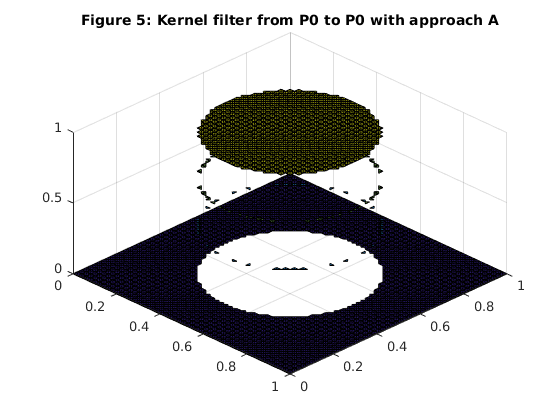

ss.filterType = 'P1';
ss.mesh       = mesh;
ss.approach   = 'A';
ss.test       = P0Function.create(mesh,1);
ss.trial      = P0Function.create(mesh,1);
filter        = Filter.create(ss);
fP0P0A        = filter.compute(fun,'QUADRATICMASS');
fP0P0A.plot()
view(45,45)
title('Figure 5: Kernel filter from P0 to P0 with approach A')

error.compute(fP0P0A,fun)

ans = 0.0014

Let's filter from P0 to P1:

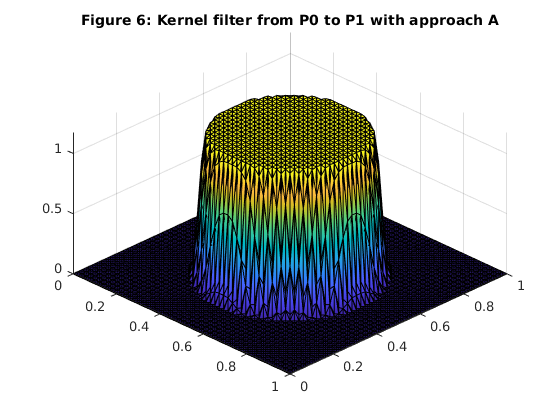

ss.test  = P0Function.create(mesh,1);
ss.trial = P1Function.create(mesh,1);
filter   = Filter.create(ss);
fP0P1A   = filter.compute(fun,'QUADRATICMASS');
fP0P1A.plot()
view(45,45)
title('Figure 6: Kernel filter from P0 to P1 with approach A')

error.compute(fP0P1A,fun)

ans = 0.0057

Let's filter from P1 to P0:

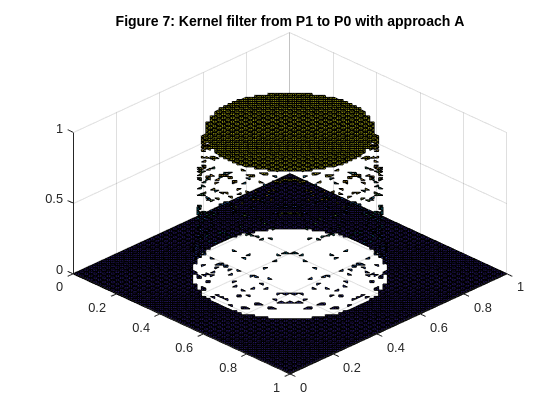

ss.test  = P1Function.create(mesh,1);
ss.trial = P0Function.create(mesh,1);
filter   = Filter.create(ss);
fP1P0A   = filter.compute(fun,'QUADRATICMASS');
fP1P0A.plot()
view(45,45)
title('Figure 7: Kernel filter from P1 to P0 with approach A')

error.compute(fP1P0A,fun)

ans = 0.0025

Let's filter from P1 to P1:

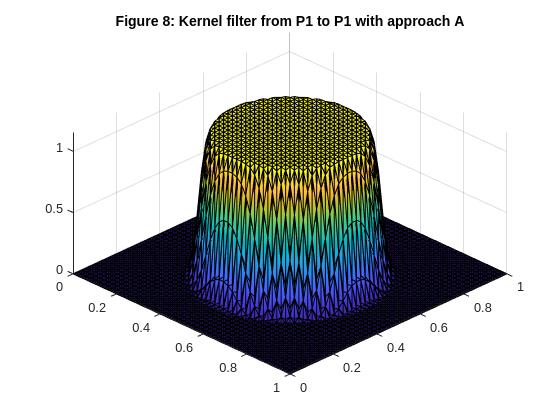

ss.test  = P1Function.create(mesh,1);
ss.trial = P1Function.create(mesh,1);
filter   = Filter.create(ss);
fP1P1A   = filter.compute(fun,'QUADRATICMASS');
fP1P1A.plot()
view(45,45)
title('Figure 8: Kernel filter from P1 to P1 with approach A')

error.compute(fP1P1A,fun)

ans = 0.0061

Let's finish with approach B.

Let's filter from P0 to P0:

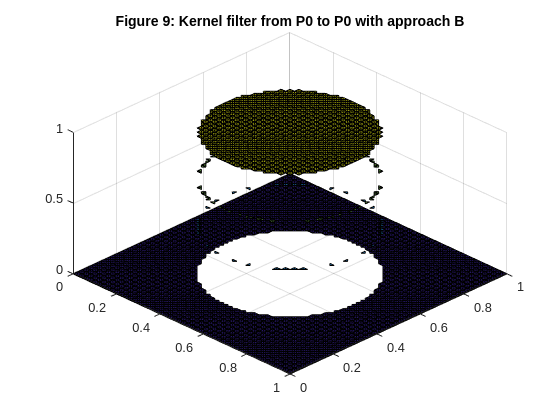

ss.approach = 'B';
ss.test     = P0Function.create(mesh,1);
ss.trial    = P0Function.create(mesh,1);
filter      = Filter.create(ss);
fP0P0B      = filter.compute(fun,'QUADRATICMASS');
fP0P0B.plot()
view(45,45)
title('Figure 9: Kernel filter from P0 to P0 with approach B')

error.compute(fP0P0B,fun)

ans = 0.0014

Let's filter from P0 to P1:

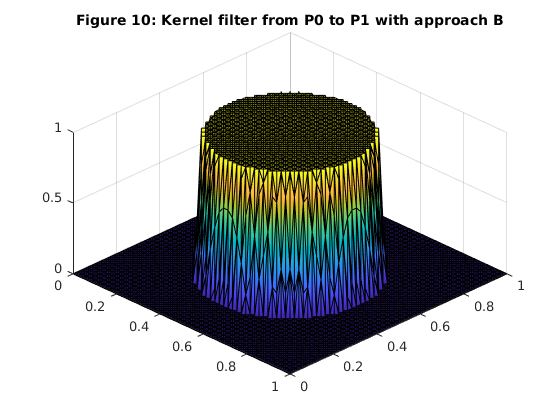

ss.test  = P0Function.create(mesh,1);
ss.trial = P1Function.create(mesh,1);
filter   = Filter.create(ss);
fP0P1B   = filter.compute(fun,'QUADRATICMASS');
fP0P1B.plot()
view(45,45)
title('Figure 10: Kernel filter from P0 to P1 with approach B')

error.compute(fP0P1B,fun)

ans = 0.0021

Let's filter from P1 to P0:

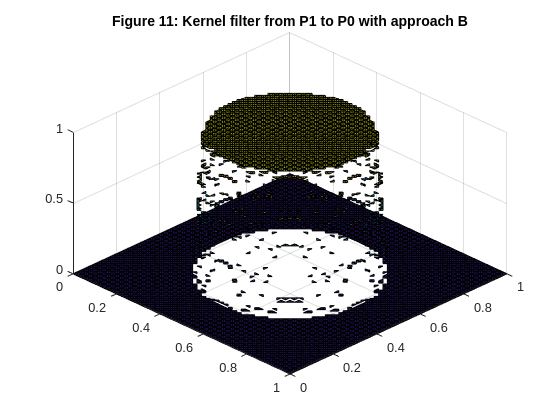

ss.test  = P1Function.create(mesh,1);
ss.trial = P0Function.create(mesh,1);
filter   = Filter.create(ss);
fP1P0B   = filter.compute(fun,'QUADRATICMASS');
fP1P0B.plot()
view(45,45)
title('Figure 11: Kernel filter from P1 to P0 with approach B')

error.compute(fP1P0B,fun)

ans = 0.0025

Let's filter from P1 to P1:

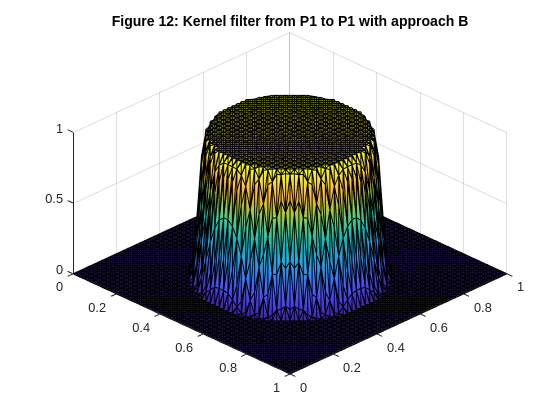

ss.test  = P1Function.create(mesh,1);
ss.trial = P1Function.create(mesh,1);
filter   = Filter.create(ss);
fP1P1B   = filter.compute(fun,'QUADRATICMASS');
fP1P1B.plot()
view(45,45)
title('Figure 12: Kernel filter from P1 to P1 with approach B')

error.compute(fP1P1B,fun)

ans = 0.0033

Original P0 to P1:

ss.approach = 'C';
ss.test     = P1Function.create(mesh,1);
ss.trial    = P0Function.create(mesh,1);
filter      = Filter.create(ss);
fOrig       = filter.compute(fun,'QUADRATICMASS');
fOrig.plot()
view(45,45)
title('Figure 13: Original P1 filter from P0 to P1')
error.compute(fOrig,fun)

ans = 0.0050

### Mesh convergence study

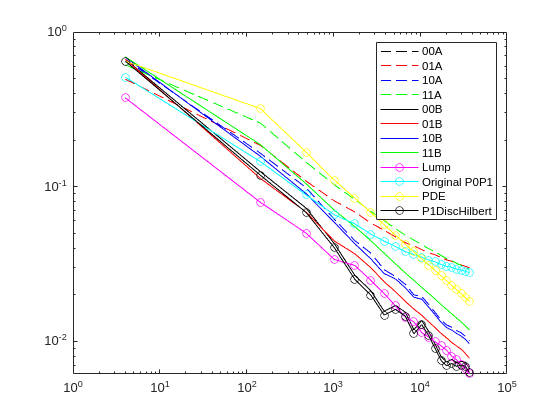

nodesAlongDir = 2:5:101;

ss            = [];
ss.filterType = 'P1';
ss.approach   = 'B';
for i = 1:length(nodesAlongDir)
    nX = nodesAlongDir(i);
    x1 = linspace(0,1,nX);
    x2 = linspace(0,1,nX);
    [xv,yv] = meshgrid(x1,x2);
    [F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');
    m.coord  = V(:,1:2);
    m.connec = F;
    mesh     = Mesh(m);
    nEl(i)   = mesh.nelem;

    s.mesh = mesh;
    fun    = AnalyticalFunction(s);

    newProj = Projector_toP1Lumped(s);
    fP1Lump = newProj.project(fun);

     ssa.approach = 'A';
     ssa.filterType = 'P1';
    ssa.mesh  = mesh;
    ssa.test  = P0Function.create(mesh,1);
    ssa.trial = P0Function.create(mesh,1);
    filter   = Filter.create(ssa);
    fP0P0A   = filter.compute(fun,'QUADRATICMASS');

    ssa.test  = P0Function.create(mesh,1);
    ssa.trial = P1Function.create(mesh,1);
    filter   = Filter.create(ssa);
    fP0P1A   = filter.compute(fun,'QUADRATICMASS');

    ssa.test  = P1Function.create(mesh,1);
    ssa.trial = P0Function.create(mesh,1);
    filter   = Filter.create(ssa);
    fP1P0A   = filter.compute(fun,'QUADRATICMASS');

    ssa.test  = P1Function.create(mesh,1);
    ssa.trial = P1Function.create(mesh,1);
    filter   = Filter.create(ssa);
    fP1P1A   = filter.compute(fun,'QUADRATICMASS');

    ssb.approach = 'B';
    ssb.filterType = 'P1';
    ssb.mesh  = mesh;
    ssb.test  = P0Function.create(mesh,1);
    ssb.trial = P0Function.create(mesh,1);
    filter   = Filter.create(ssb);
    fP0P0B   = filter.compute(fun,'QUADRATICMASS');

    ssb.test  = P0Function.create(mesh,1);
    ssb.trial = P1Function.create(mesh,1);
    filter   = Filter.create(ssb);
    fP0P1B   = filter.compute(fun,'QUADRATICMASS');

    ssb.test  = P1Function.create(mesh,1);
    ssb.trial = P0Function.create(mesh,1);
    filter   = Filter.create(ssb);
    fP1P0B   = filter.compute(fun,'QUADRATICMASS');

    ssb.test  = P1Function.create(mesh,1);
    ssb.trial = P1Function.create(mesh,1);
    filter   = Filter.create(ssb);
    fP1P1B   = filter.compute(fun,'QUADRATICMASS');

    ssc.mesh  = mesh;
    ssc.approach = 'C';
    ssc.filterType = 'P1';
    ssc.test     = P1Function.create(mesh,1);
    ssc.trial    = P0Function.create(mesh,1);
    filter      = Filter.create(ssc);
    fOrig       = filter.compute(fun,'QUADRATICMASS');


    ss.filterType   = 'PDE';
    ss.mesh         = mesh;
    ss.boundaryType = 'Neumann';
    ss.metric       = 'Isotropy';
    filter          = Filter.create(ss);
    fP1PDE          = filter.compute(fun,'QUADRATICMASS');

    fP1Disc = fun.project('H1P1D');


    iPar.mesh     = mesh;
    refError      = IntegratorScalarProduct(iPar);
    refEr         = 0.5*refError.compute(fun,fun);

    error         = IntegratorError(iPar);

    er00A(i)         = error.compute(fP0P0A,fun)/refEr;
    er01A(i)         = error.compute(fP0P1A,fun)/refEr;
    er10A(i)         = error.compute(fP1P0A,fun)/refEr;
    er11A(i)         = error.compute(fP1P1A,fun)/refEr;
    er00B(i)         = error.compute(fP0P0B,fun)/refEr;
    er01B(i)         = error.compute(fP0P1B,fun)/refEr;
    er10B(i)         = error.compute(fP1P0B,fun)/refEr;
    er11B(i)         = error.compute(fP1P1B,fun)/refEr;
    erLump(i)         = error.compute(fP1Lump,fun)/refEr;
    erOrig(i)       = error.compute(fOrig,fun)/refEr;
    ePDE(i)          = error.compute(fP1PDE,fun)/refEr;
    eP1Disc(i)       = error.compute(fP1Disc,fun)/refEr;
end
loglog(nEl,er00A,'--k',nEl,er01A,'--r',nEl,er10A,'--b',nEl,er11A,'--g',nEl,er00B,'k',nEl,er01B,'r',nEl,er10B,'b',nEl,er11B,'g',nEl,erLump,'-om',nEl,erOrig,'-oc',nEl,ePDE,'-oy',nEl,eP1Disc,'-ok')
legend('00A','01A','10A','11A','00B','01B','10B','11B','Lump','Original P0P1','PDE','P1DiscHilbert')